## Antenna 2017

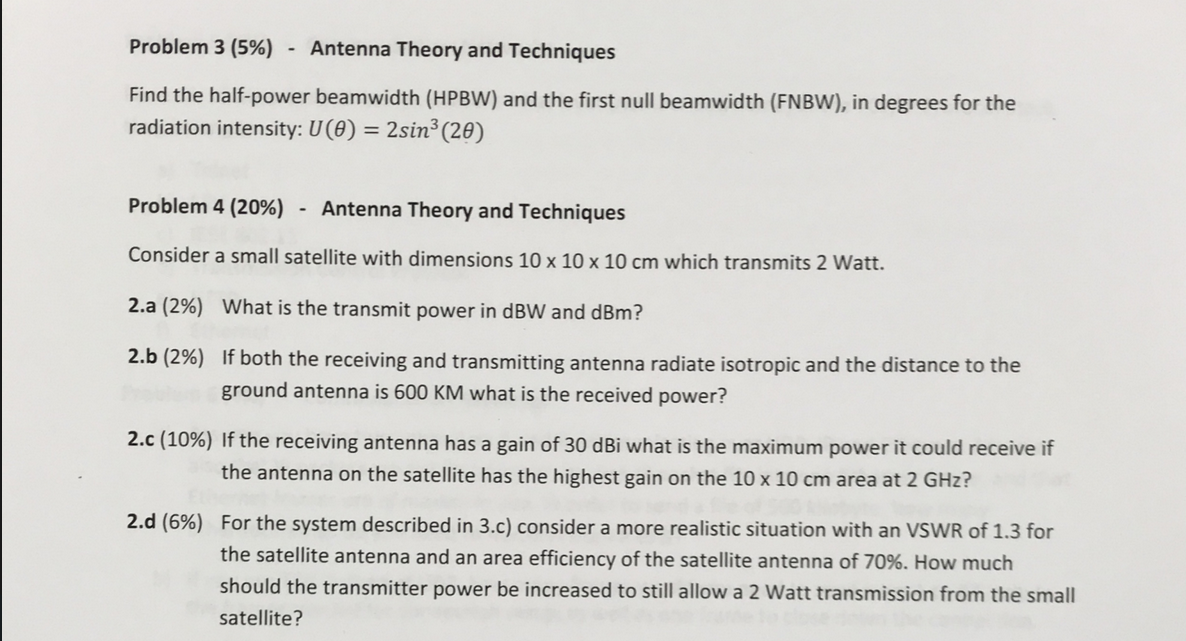

Problem 3

syms t
expr = 2*sin(2*t)^3;
HPBW = solve(expr == 1/2,t);
vpa(HPBW)

$$ans = \left(\begin{array}{c} -0.13875892755324046970727300517205+0.27027707384014488384354657689239\,\mathrm{i}\\ -0.13875892755324046970727300517205-0.27027707384014488384354657689239\,\mathrm{i}\\ 0.34075119084070677047793171607945\\ 1.2300451359541898487533899755603\\ 1.7095552543481370889385946968118-0.27027707384014488384354657689239\,\mathrm{i}\\ 1.7095552543481370889385946968118+0.27027707384014488384354657689239\,\mathrm{i} \end{array}\right)$$

vpa(rad2deg(HPBW(4)-HPBW(3)))

$$ans = 50.952789801541257673620208804112$$

% For First null beamwidth så bruger vi chats svar istedet

Solution:

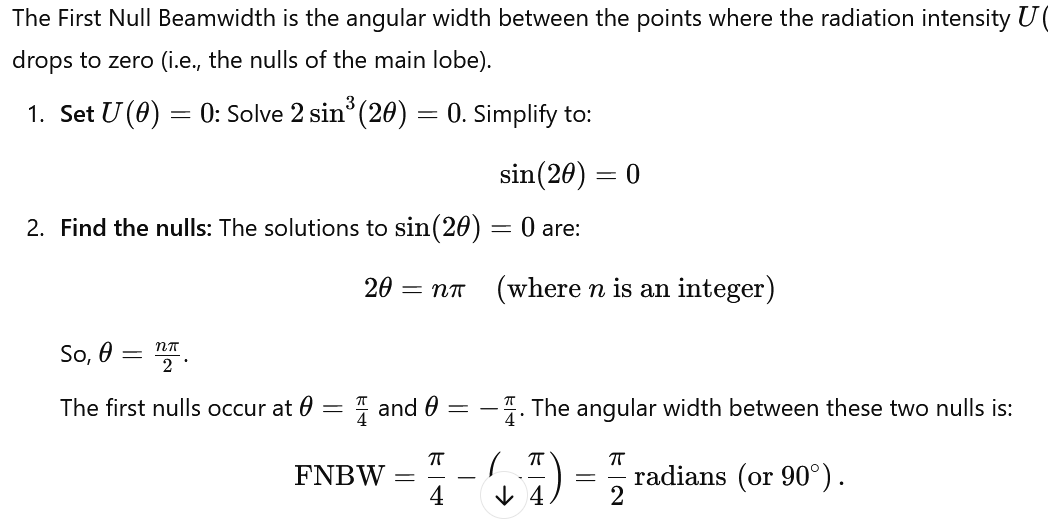

Problem 4

2.a: Solution:

antenna_size = 10*10*10;
Powert = 2;
powerDb = pow2db(Powert); %dBW
dBWtodBm = 30 + powerDb;


2.b Hvor helvede er den her formel? Solution:

receiveGain = 30 %dbi

receiveGain =     30


2.c Solution:  

Gt = (4*pi*1*0.1*0.1)/((3e8/2e9)^2);
Gr = db2pow(receiveGain);
Pr = Powert*(3e8/2e9)^2 * ((Gt*Gr)/(4*pi*600E3)^2);
picoWatt = num2sip(Pr)

picoWatt = '4.421 p'

todBm = 10*log10((Pr*1000)/1) % final answer

todBm =           -83.544823691254


2.d Solution: The loss from VSWR is defined as:


$$L_{\textrm{VSWR}} =1-{\left(\frac{\textrm{VSWR}-1}{\textrm{VSWR}+1}\right)}^2$$



$$P_{\textrm{in}} =\frac{P_{\textrm{effective}} }{\eta }$$


Therefor the transmitter the total power is described: $P_{\textrm{transmitter}} =\frac{P_{\textrm{effective}} }{\eta \cdot L_{\textrm{VSWR}} }$

Lvswr = 1-((1.3-1)/(1.3+1))^2;
eta = 0.7;
Peffective = 2;
Ptransmitter = Peffective/(eta*Lvswr); % for at tillade effektiv 2w skal der bruges 2.9 W istedet. 